**NAME: ABHISHEK TRIPATHI**

**MATRICULATION NUMBER: 03786108**

**ELEMENTS OF MACHINE LEARNING ASSIGNMENT: VERSION A**

- **DATA ANALYSIS**

**CODE:**

%% Concrete Data Analysis and Machine Learning

clc;
clear;
close all;
% Load the dataset excel file
filename = 'F:\seminar of machine elements exam\Concrete_Data.xls';
data = readmatrix(filename);

% Extract features and target variable
X = data(:,1:end-1);  % Input features
y = data(:,end);      % Target variable (Concrete Compressive Strength)
%% 1. Exploratory Data Analysis (EDA)

% Summary statistics
feature_mean = mean(X);
feature_std = std(X);
disp('Feature Means:');

Feature Means:


disp(feature_mean);

  281.1656   73.8955   54.1871  181.5664    6.2031  972.9186  773.5789   45.6621



disp('Feature Standard Deviations:');

Feature Standard Deviations:


disp(feature_std);

  104.5071   86.2791   63.9965   21.3556    5.9735   77.7538   80.1754   63.1699



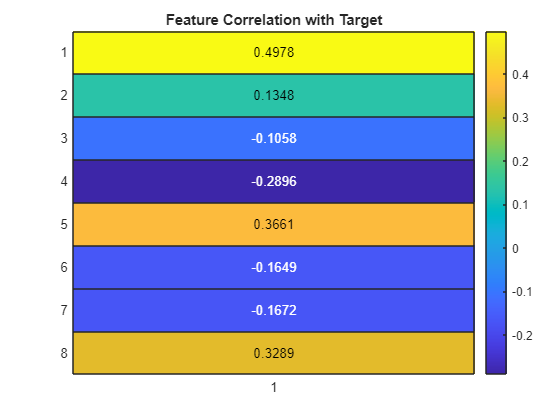

% Correlation matrix
corrMatrix = corr(X, y);
figure;
heatmap(corrMatrix, 'Colormap', parula);
title('Feature Correlation with Target');



% Visualizing distributions of features
figure;
for i = 1:size(X,2)
    subplot(3,3,i);
    histogram(X(:,i));
    title(['Feature ', num2str(i)]);
end
sgtitle('Feature Distributions');




% Outlier Detection using Z-score
z_scores = zscore(X);
outlier_idx = any(abs(z_scores) > 3, 2);
X_clean = X(~outlier_idx, :);
y_clean = y(~outlier_idx);

%% 2. Supervised Learning - Splitting Data
rng(1); % For reproducibility
train_ratio = 0.8;
n = size(X_clean, 1);
idx = randperm(n);
train_idx = idx(1:round(train_ratio*n));
test_idx = idx(round(train_ratio*n)+1:end);

X_train = X_clean(train_idx, :);
y_train = y_clean(train_idx);
X_test = X_clean(test_idx, :);
y_test = y_clean(test_idx);

%% 2.1 Linear Regression
mdl_linear = fitlm(X_train, y_train);
y_pred_linear = predict(mdl_linear, X_test);
linear_rmse = sqrt(mean((y_test - y_pred_linear).^2));

%% 2.2 Ridge Regression (Cross-validation for Lambda)
lambda_values = logspace(-2, 2, 10);
ridge_rmse = zeros(length(lambda_values), 1);

for i = 1:length(lambda_values)
    B = ridge(y_train, X_train, lambda_values(i), 0);
    y_pred_ridge = [ones(size(X_test,1),1) X_test] * B;
    ridge_rmse(i) = sqrt(mean((y_test - y_pred_ridge).^2));
end

% Optimal Lambda
[~, best_lambda_idx] = min(ridge_rmse);
best_lambda = lambda_values(best_lambda_idx);
fprintf('Optimal Lambda for Ridge Regression: %f\n', best_lambda);

Optimal Lambda for Ridge Regression: 0.010000


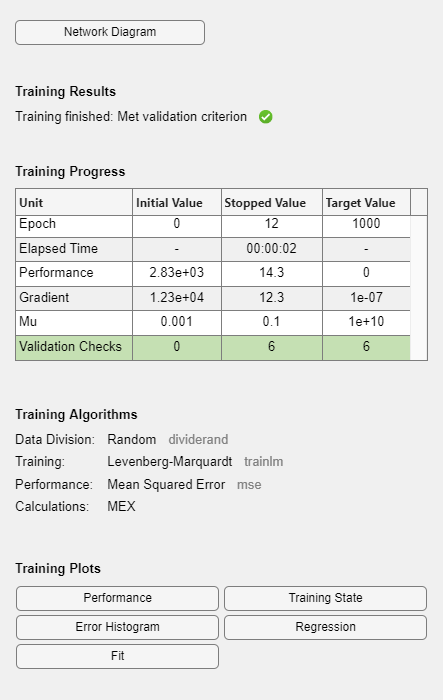


%% 2.3 Neural Network Regression
net = fitnet([10,10]);  % 2 hidden layers with 10 neurons each
net = train(net, X_train', y_train');

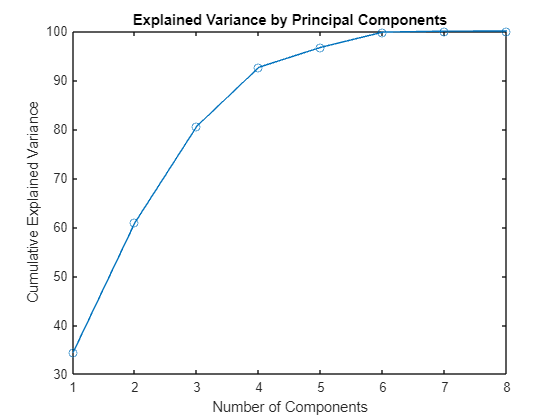

y_pred_nn = net(X_test');
nn_rmse = sqrt(mean((y_test - y_pred_nn').^2));

%% 3. Dimensionality Reduction - PCA
[coeff, score, ~, ~, explained] = pca(X_clean);
figure;
plot(cumsum(explained), '-o');
title('Explained Variance by Principal Components');
xlabel('Number of Components');
ylabel('Cumulative Explained Variance');


% Selecting enough components to explain 95% variance
num_components = find(cumsum(explained) >= 95, 1);
X_pca_train = score(train_idx, 1:num_components);
X_pca_test = score(test_idx, 1:num_components);

mdl_pca = fitlm(X_pca_train, y_train);
y_pred_pca = predict(mdl_pca, X_pca_test);
pca_rmse = sqrt(mean((y_test - y_pred_pca).^2));

%% 3.3 Manual Feature Selection (Water-Binder Ratio)
wb_ratio = X(:,4) ./ (X(:,1) + X(:,2) + X(:,3) + X(:,5)); % Water/(Cement+Slag+FlyAsh+Superplasticizers)
X_manual = [X(:,6:8), wb_ratio]; % Keeping 4 features
X_manual_train = X_manual(train_idx, :);
X_manual_test = X_manual(test_idx, :);

mdl_manual = fitlm(X_manual_train, y_train);
y_pred_manual = predict(mdl_manual, X_manual_test);
manual_rmse = sqrt(mean((y_test - y_pred_manual).^2));

%% Display Results
fprintf('Linear Regression RMSE: %.3f\n', linear_rmse);

Linear Regression RMSE: 10.052


fprintf('Best Ridge Regression RMSE (λ=%.3f): %.3f\n', best_lambda, min(ridge_rmse));

Best Ridge Regression RMSE (λ=0.010): 10.052


fprintf('Neural Network Regression RMSE: %.3f\n', nn_rmse);

Neural Network Regression RMSE: 6.547


fprintf('PCA Regression RMSE: %.3f\n', pca_rmse);

PCA Regression RMSE: 14.866


fprintf('Manual Feature Selection RMSE: %.3f\n', manual_rmse);

Manual Feature Selection RMSE: 16.048
